## Wczytanie nagrań

% files = {
%     'data/prawo_1.wav'
%     'data/prawo_2.wav'
%     'data/prawo_3.wav'
%     'data/lewo_1.wav'
%     'data/lewo_2.wav'
%     'data/lewo_3.wav'
%     'data/stop_1.wav'
%     'data/stop_2.wav'
%     'data/stop_3.wav'
%     'data/start_1.wav'
%     'data/start_2.wav'
%     'data/start_3.wav'
% };
% 
% labels = [1 1 1 2 2 2 3 3 3 4 4 4];
% 
% names = {
%     'prawo'
%     'lewo'
%     'stop'
%     'start'
% };
% 
% % zakładamy takie samo fs dla wszystkich nagrań
% [~, fs] = audioread(files{1});
% 
% data = {};
% 
% for k=1:length(files)
%     data{k} = audioread(files{k});
%     data{k} = data{k} / max(data{k});
% end


### Podział na zbiór treningowy i testowy

% train_ids = [1 2 4 5 7 8 10 11];
% 
% test_ids = [3 6 9 12];

## Przetwarzanie i normalizacja danych

W tym miejscu następuje przygotowanie danych do dalszej analizy. Zależnie od wybranego sposobu liczenia cech może tutaj następować wyrównanie długości nagrań, normalizacja głośności, wycinanie gragmentów ciszy itp. 

for k=1:length(data)
    data{k} = preprocess(data{k});
end

## Ekstrakcja wektora cech

Dla każdego nagrania należy wyznaczyć jego reprezentację. Powinna ona być kompaktowa, mieć dużo wspólnych cech dla nagrań tego samego słowa oraz dobrze rozróżniać nagrania różnych słów. Powinna być też możliwie niezależna od mówcy (w tym zadaniu nie zależy nam na identyfikacji osób). Przykładowa implementacja wykorzystuje bardzo prostą cechę: moc sygnału w różnych częstotliwościach, bez normalizacji częstotliwości bazowej.

% wyznacz jedną cechę do określenia rozmiaru wektora
% zakładamy stały rozmiar wektora cech
tmp = extract(data{1}, fs);
feats = zeros(length(tmp), length(data));

% wyznaczenie cech dla wszystkich danych
for k=1:length(data)
    feats(:,k) = extract(data{k}, fs);
end

## Trening klasyfikatora

Podstawą treningu są wektory cech i etykiety danych trenujących. Wyjściem powinien być pewien model dostępnych klas. Zależnie od wybranego klasyfikatora może mieć on różną postać. W ramach przykładu przygotowane zostały dwa proste klasyfikatory: najbliższego sąsiada (1-NN) oraz geometryczny. Klasyfikator 1-NN nie potrzebuje żadnego dodatkowego przygotowania danych - zbiór treningowy jest jednocześnie uzwanany za model. W przypadku klasyfikatora geometrycznego dla każdej z klas wyznaczane są uśrednione wektory cech i to one są zwracane jako ostateczny model. 

[model1, labels1] = fit_1nn(feats(:, train_ids), train_lbl(train_ids))

model1 =     0.0000    0.0001    0.0000    0.0000    0.0000    0.0000    0.0001    0.0000    0.0000    0.0001    0.0001    0.0000    0.0014    0.0014    0.0010    0.0018    0.0005    0.0012    0.0004    0.0005    0.0014    0.0020    0.0086    0.0074    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0001    0.0001    0.0000    0.0000    0.0000    0.0083    0.0023    0.0416    0.0137    0.0085    0.0024    0.0220    0.1934    0.3985    0.0170    0.0150    0.0339    0.0000    0.0000
    0.0013    0.0008    0.0002    0.0002    0.0003    0.0002    0.0006    0.0003    0.0002    0.0008    0.0005    0.0012    0.0159    0.0033    0.0045    0.0034    0.0060    0.0293    0.0027    0.0018    0.0073    0.0082    0.0262    0.0021    0.0004    0.0006    0.0004    0.0004    0.0005    0.0004    0.0014    0.0013    0.0021    0.0020    0.0014    0.0009    0.0164    0.0144    0.0051    0.0044    0.0121    0.0026    0.0458    0.0202    0.0281    0.0214    0.0112    0.0225    0.0004

labels1 =      1     1     1     2     2     2     3     3     3     4     4     4     1     1     1     2     2     2     3     3     3     4     4     4     1     1     1     2     2     2     3     3     3     4     4     4     1     1     1     2     2     2     3     3     3     4     4     4     1     1


[model2, labels2] = fit_geom(feats(:, train_ids), train_lbl(train_ids))

model2 =     0.0778    0.0706    0.0979    0.0920
    0.0516    0.0257    0.0689    0.0911
    0.4753    0.3655    0.3494    0.3598
    0.1539    0.1196    0.0974    0.1959
    0.2676    0.3101    0.2089    0.2260
    0.1449    0.1369    0.0850    0.1390
    0.1174    0.1698    0.1107    0.1023
    0.2702    0.2647    0.2932    0.1532
    0.2882    0.2798    0.4343    0.1791
    0.3407    0.3786    0.4039    0.2780


labels2 =      1     2     3     4


## Test klasyfikatora k-NN

Wykorzystując wytrenowane modele i podzbiór testowy można wyznaczyć ich predykcje i określić skuteczność klasyfikacji.

cls1 = predict_knn(feats(:, test_ids), model1, labels1, 28, 'majority_voting', 'cityblock');

Znając oczekiwane etykiety dla klas można wyznaczyć skuteczność (liczbę poprawnych klasyfikacji):

all_labels = [train_lbl test_lbl];
cls_true = all_labels(test_ids);
acc1 = sum(cls1 == cls_true) / length(cls1)

acc1 = 0.4861

Dokładniejsza analiza błędów może być dokonana przy użyciu macierzy pomyłek:

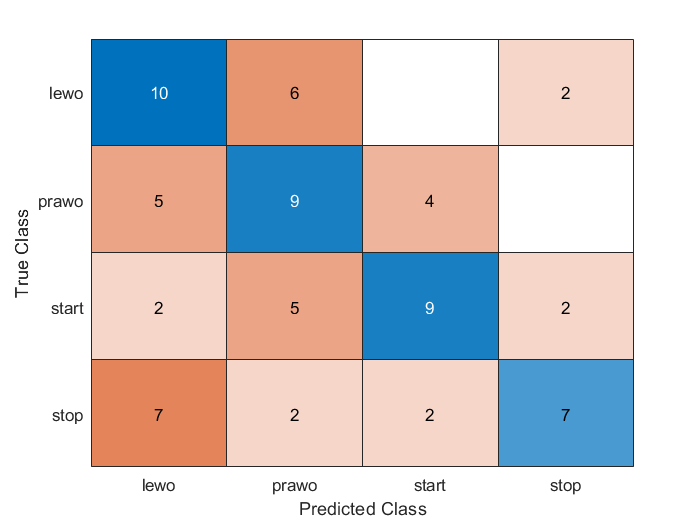

figure;
confusionchart(confusionmat(cls_true, cls1), names)

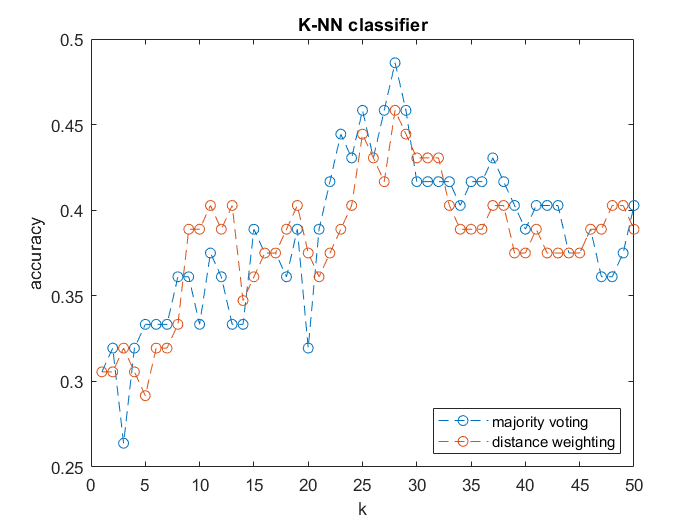

compare_knn(feats, test_ids, model1, labels1, train_lbl, test_lbl, 50, 'cityblock');

## Test klasyfikatora geometrycznego

cls2 = predict_geom(feats(:, test_ids), model2, labels2);
acc2 = sum(cls2 == cls_true) / length(cls2)

acc2 = 0.4306

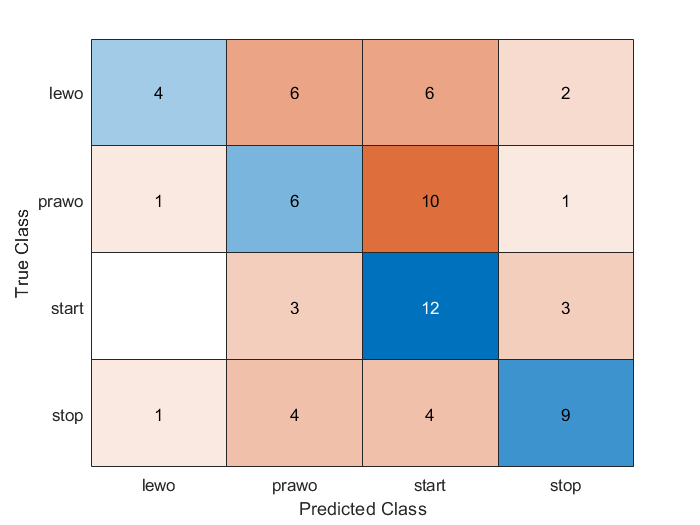

figure;
confusionchart(confusionmat(cls_true, cls2), names)

## Detekcja słów kluczowych w strumieniu

Dzieląc długie nagranie na (nakładające się) okna o ustalonej długości możemy każde z nich przepuścić przez wybrany klasyfikator. 

% % ważne założenie: nagranie ma takie samo Fs jak dane treningowe
% stream = audioread('data/stream.wav');
% 
% % zakładana długość i overlap słowa kluczowego (liczba próbek)
% len = round(0.8 * fs);
% overlap = round(0.1 * fs);
% 
% cls = zeros(length(stream), 1);
% dst = zeros(length(stream), 1);
% 
% for k=1:overlap:length(stream)-len
%     r = stream(k:k+len);
%     r = preprocess(r, fs);
%     f = extract(r, fs);
%     [cls(k:k+len), dst(k:k+len)] = predict_1nn(f, model1, labels1);
% end

Klasyfikator zawsze daje jakąś odpowiedź, ale przyjmując pewne założenie dotyczące progu odległości możemy wyciąć predykcje niepewne:

% figure; plot(cls); hold on; plot(dst); hold off; legend(["klasa", "dystans"]);
% cls_filt = cls;
% cls_filt(dst > 0.3) = 0;
% figure; plot(cls_filt); hold on; plot(dst); hold off; legend(["klasa", "dystans"]);

## Analiza jakości detekcji

% % wczytanie etykiet nagrania testowego
% lbls = load('data/labels.txt');
% 
% figure; plot(lbls); hold on; plot(cls_filt); legend("Oczekiwane", "Predykcja");

Jakość detekcji można określić na podstawie różnych wskaźników. Jednym z popularnych jest indeks Jaccarda, zwany też IoU (intersection over union). Dla każdej z klas niezależnie wyznaczamy stosunek wszystkich próbek poprawnie sklasyfikowanych (część wspólna) do wszystkich rpóbek oznaczonych jako dana klasa w etykietach oraz predykcji (suma):

% acc_1 = sum(lbls == 1 & cls_filt == 1) / sum(lbls == 1 | cls_filt == 1)

Jest też oczywiście do tego gotowa funkcja:

% jaccard(cls_filt, lbls)

## Definicje funkcji

### Przetwarzanie wstępne

function y = preprocess(x, fs)
    y = x / max(x);
end

### Ekstrakcja wektora cech

function f = extract(x, fs)
    nfft = 256;
    f = pwelch(x, 1024, 256, nfft, fs);
    f = f / max(f);
end

### Klasyfikator 1-NN

function [model, labels] = fit_1nn(x, y)
    model = x;
    labels = y;
end

function [cls, dst] = predict_1nn(feats, model, labels)
    % wyznacz wszystkie odległości pomiędzy wektorami cech feats a modelem
    dm = pdist2(feats', model', 'cosine');
    
    % znajdź najmniejszą wartość dla każdego wiersza (próbki testowej)
    [dst, min_idx] = min(dm, [], 2);
    
    % określ klasę dla każdej próbki
    cls = labels(min_idx);
end

### Klasyfikator geometryczny

function [model, labels] = fit_geom(x, y)
    cls_num = max(y);
    
    model = zeros(size(x,1), cls_num);
    
    % średnia ze wszystkich kolumn o tej samej etykiecie klasy
    for k = 1:cls_num
        model(:,k) = mean(x(:, y==k), 2);
    end
    
    % po jednej wartości dla każdej klasy
    labels = 1:cls_num;
end

function [cls, dst] = predict_geom(feats, model, labels)
    % wyznacz wszystkie odległości pomiędzy wektorami cech feats a modelem
    dm = pdist2(feats', model', 'cosine');
    
    % znajdź najmniejszą wartość dla każdego wiersza (próbki testowej)
    [dst, min_idx] = min(dm, [], 2);
    
    % określ klasę dla każdej próbki
    cls = labels(min_idx);
end


### **Klasyfikator k-NN**

function [cls, dst] = predict_knn(feats, model, labels, k, type, metric)
    % wyznacz wszystkie odległości pomiędzy wektorami cech feats a modelem
    dm = pdist2(feats', model', metric);
    
    
    % znajdź k-najmniejszych wartości dla każdego wiersza (próbki testowej)
    [dst, min_idx] = mink(dm, k, 2);
    classes = labels(min_idx);
    
    if (k==1)
        classes = classes';
    end
    
    if (strcmp(type,'distance_weighting')) 
        [rows, cols] = size(classes);
        num_of_classes = 4;
        weighted_classes_raw = zeros(rows, num_of_classes);
        for row=1:rows
            for col=1:cols
                class_now = classes(row,col);
                inv_dist = 1/dst(row,col);
                if class_now == 1
                    weighted_classes_raw(row,1) = weighted_classes_raw(row,1) + inv_dist;
                elseif class_now == 2
                    weighted_classes_raw(row,2) = weighted_classes_raw(row,2) + inv_dist;
                elseif class_now == 3
                    weighted_classes_raw(row,3) = weighted_classes_raw(row,3) + inv_dist;
                elseif class_now == 4
                    weighted_classes_raw(row,4) = weighted_classes_raw(row,4) + inv_dist;               
                end
            end
        end
        
        weighted_classes_raw_idx = zeros(rows, 1);
        for j=1:rows
            [~, I] = max(weighted_classes_raw(j,:));
            weighted_classes_raw_idx(j) = I;
        end
        
        cls_k_n_weighted = weighted_classes_raw_idx';
        cls = cls_k_n_weighted;
        
    elseif (strcmp(type,'majority_voting'))
        M = mode(classes,2);
        cls_k_n = M';
        cls = cls_k_n;
    end
    
end

### **Porównanie działania **

function [] = compare_knn(feats, test_ids, model1, labels1, train_lbl, test_lbl, kmax, metric)
acc_vect_majority = zeros(kmax, 1);
for k=1:kmax
    cls1 = predict_knn(feats(:, test_ids), model1, labels1, k, 'majority_voting', metric);
    all_labels = [train_lbl test_lbl];
    cls_true = all_labels(test_ids);
    acc1 = sum(cls1 == cls_true) / length(cls1);
    acc_vect_majority(k) = acc1;
end

acc_vect_dist = zeros(kmax, 1);
for k=1:kmax
    cls1 = predict_knn(feats(:, test_ids), model1, labels1, k, 'distance_weighting', metric);
    all_labels = [train_lbl test_lbl];
    cls_true = all_labels(test_ids);
    acc1 = sum(cls1 == cls_true) / length(cls1);
    acc_vect_dist(k) = acc1;
end

figure;
plot(acc_vect_majority,'--o', 'LineWidth', 0.5);
hold on;
plot(acc_vect_dist,'--o', 'LineWidth', 0.5);
legend('majority voting', 'distance weighting', 'Location',"southeast");
title("K-NN classifier");
xlabel("k");
ylabel("accuracy");
end